# Subset Histone Flux Correlation

Author: Scott Campit

clear all

## Clean up the datasets

First, let's compare the CCLE metabolic models to the CCLE proteomics dataset. We'll first analyze the data from a pan cancer perspective, then we'll parse out cancer cell lines by tissue, medium, and culture morphology.

% Load data
load ~/Data/CBM/eGEM/_Fluxes/CCLE_fluxes_all.mat
load ~/Data/Proteomics/CCLE/CCLE_Proteomics.mat
load ~/Data/RNASeq/CCLE/CCLE_RNASeq.mat

Set errors from the constraint-based models to 0.

for i = 1:length(flux)
    tmp = flux{i};
    tmp(isnan(tmp)) = 0;
    flux{i} = tmp;
end

Get the intersetion between the CCLE proteomics dataset and the CCLE metabolic fluxes.

% Get intersection between both datasets (CCLE)
[~, ia, ib]      = intersect(string(cell_lines), string(cell_names));
ccle_proteomics  = proteomics(ib, :);
cell_names       = cell_names(ib);
tissues          = tissues(ib);
medium           = medium(ib);
cultures         = cultures(ib);

Clean up the marker data.

% CCLE
marks = regexprep(marks, 'K[0-9]*ac0', '');
marks = regexprep(marks, 'K[0-9]*me0', '');

Let's get the methylation markers first.

% Parse out methylation marks specifically
methylation_idx = [2, 3, ...         % H3K4
                   6, 7, 8, ...      % H3K9
                   21, 22, 23, ...   % H3K36
                   24, 28, 31, ...   % H3K27
                   41, 42];          % H3K79
               
methylation_marks = marks(methylation_idx);
methylation_data  = ccle_proteomics(:, methylation_idx);

Now let's get the acetylation markers.

acetylation_idx   = [4, ...  H3K4
                     9, ...  H3K9
                     10, ... H3K14
                     16, ... H3K18
                     17, ... H3K23
                     33];  % H3k27
acetylation_marks = marks(acetylation_idx);
acetylation_data = ccle_proteomics(:, acetylation_idx);

single_proteomics = [acetylation_data, methylation_data];
single_marks      = [acetylation_marks, methylation_marks];

## Clustering based on tissue subtypes

To perform this analysis in a high throughput fashion, I need to design a function that will allow me to take the current structure of the dataset, and output correlation matrices, stored in individual cells within a cell array. This operation will be iterated across all tissues.

final_data = [];
for t = 1:length(unique(tissues))
    tmp = unique(tissues);
    idx = ismember(tissues, tmp(t));
    subset_methylation = methylation_data(idx, :);
    subset_acetylation = acetylation_data(idx, :);
    
    for i = 1:length(flux)
        tmp = flux{i};
        tmp2 = tmp(:, idx);
        subset_flux{i} = tmp2;
    end
    
    %% Compute correlations for mono-methylated markers and bulk mono-methylation
    me1 = [1, 3, 6, 9, 12];
    for i = 1:length(me1)
        [me1_r(i), me1_p(i)] = corr(methylation_data(idx, me1(i)), subset_flux{3}(3775, :)');
    end
    
    % Show the data
    me1_data = [string(methylation_marks(me1)'), me1_r', me1_p'];
    
    %% Compute correlations for di-methylated markers and bulk di-methylation
    me2 = [2, 4, 7, 10, 13];
    for i = 1:length(me2)
        [me2_r(i), me2_p(i)] = corr(methylation_data(idx, me2(i)), subset_flux{4}(3776, :)');
    end
    
    % Show the data
    me2_data = [string(methylation_marks(me2)'), me2_r', me2_p'];
    
    %% Compute correlations for tri-methylated markers and bulk tri-methylation
    me3 = [5, 8, 11];
    clear r p
    for i = 1:length(me3)
        [me3_r(i), me3_p(i)] = corr(methylation_data(idx, me3(i)), subset_flux{5}(3777, :)');
    end
    
    % Show the data
    me3_data = [string(methylation_marks(me3)'), me3_r', me3_p'];
    
    %% Compute correlations for acetylated markers and bulk acetylation
    for i = 1:length(acetylation_marks)
        [ac_r(i), ac_p(i)] = corr(acetylation_data(idx, i), subset_flux{1}(3773, :)');
    end
    
    % Show the data
    ac_data = [string(acetylation_marks'), ac_r', ac_p'];
    
    bulk_ccle = [me1_data; me2_data; me3_data; ac_data];
    bulk_labels = repmat("Bulk", [size(bulk_ccle, 1), 1]);
    
    % H3K4
    [r(1), p(1)] = corr(methylation_data(idx, 1), subset_flux{6}(3780, :)'); % H3K4me1
    [r(2), p(2)] = corr(methylation_data(idx, 2), subset_flux{7}(3781, :)'); % H3K4me2
    
    % H3K9
    [r(3), p(3)] = corr(methylation_data(idx, 3), subset_flux{10}(3784, :)'); % H3K9me1
    [r(4), p(4)] = corr(methylation_data(idx, 4), subset_flux{11}(3785, :)'); % H3K9me2
    [r(5), p(5)] = corr(methylation_data(idx, 5), subset_flux{12}(3786, :)'); % H3K9me3
    
    % H3K36
    [r(6), p(6)] = corr(methylation_data(idx, 6), subset_flux{18}(3792, :)'); % H3K36me1
    [r(7), p(7)] = corr(methylation_data(idx, 7), subset_flux{19}(3793, :)'); % H3K36me2
    [r(8), p(8)] = corr(methylation_data(idx, 8), subset_flux{20}(3794, :)'); % H3K36me3
    
    % H3K27
    [r(9), p(9)] = corr(methylation_data(idx, 9), subset_flux{14}(3788, :)'); % H3K27me1
    [r(10), p(10)] = corr(methylation_data(idx, 10), subset_flux{15}(3789, :)'); % H3K27me2
    [r(11), p(11)] = corr(methylation_data(idx, 11), subset_flux{16}(3790, :)'); % H3K27me3
    
    % H3K79
    [r(12), p(12)] = corr(methylation_data(idx, 12), subset_flux{22}(3796, :)'); % H3K79me1
    [r(13), p(13)] = corr(methylation_data(idx, 13), subset_flux{23}(3797, :)'); % H3K79me2
    
    % Acetylation
    [r(14), p(14)] = corr(acetylation_data(idx, 1), subset_flux{9}(3783, :)'); % H3K4ac1
    [r(15), p(15)] = corr(acetylation_data(idx, 2), subset_flux{13}(3787, :)'); % H3K9ac1
    [r(16), p(16)] = corr(acetylation_data(idx, 6), subset_flux{17}(3791, :)'); % H3K27ac1
    
    individual_ccle = [string([methylation_marks, acetylation_marks([1, 2, 5])]'), r', p'];
    individual_labels = repmat("Individual", [size(individual_ccle, 1), 1]);
    
    data = [bulk_ccle; individual_ccle];
    data = [data, [bulk_labels; individual_labels]];
    
    tmp = unique(tissues);
    tmp = tmp(t);
    data = [data, repmat(tmp, [size(data, 1), 1])];
    final_data = [final_data; data];
end

Multiple hypothesis correction

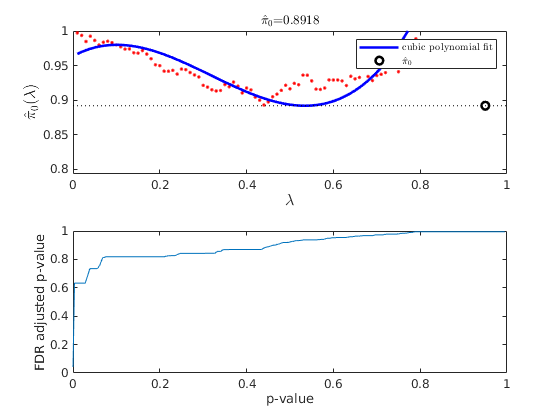

pvals = str2double(final_data(:, 3));
fdr = mafdr(pvals, 'BHFDR', true, 'Showplot', true);

final_data = [final_data, string(fdr)];

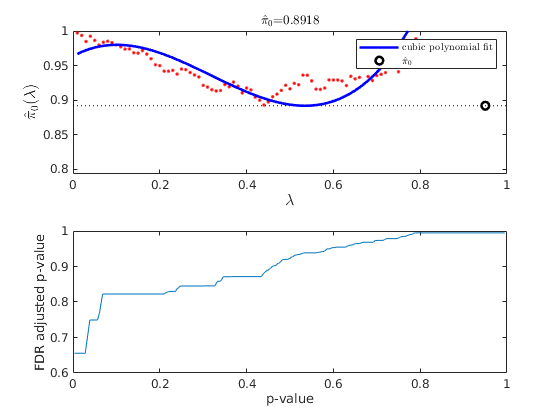

pvals = str2double(final_data(:, 3));
idx = (pvals == min(pvals));
tmp = final_data;
tmp(idx, :) = [];
pvals = str2double(tmp(:, 3));
fdr = mafdr(pvals, 'BHFDR', true, 'Showplot', true);

%final_data = [final_data, string(fdr)];

## Clustering based on tissue subtypes

To perform this analysis in a high throughput fashion, I need to design a function that will allow me to take the current structure of the dataset, and output correlation matrices, stored in individual cells within a cell array. This operation will be iterated across all tissues.

for t = 1:length(unique(cultures))
    tmp = unique(cultures);
    idx = ismember(cultures, tmp(t));
    subset_methylation = methylation_data(idx, :);
    subset_acetylation = acetylation_data(idx, :);
    subset_flux = flux(:, idx);
    %% Compute correlations for mono-methylated markers and bulk mono-methylation
    me1 = [1, 3, 6, 9, 12];
    for i = 1:length(me1)
        [me1_r(i), me1_p(i)] = corr(subset_methylation(:, me1(i)), subset_flux(5, :)');
    end
    
    % Show the data
    me1_data = [string(methylation_marks(me1)'), me1_r', me1_p'];
    
    %% Compute correlations for di-methylated markers and bulk di-methylation
    me2 = [2, 4, 7, 10, 13];
    for i = 1:length(me2)
        [me2_r(i), me2_p(i)] = corr(subset_methylation(:, me2(i)), subset_flux(6, :)');
    end
    
    % Show the data
    me2_data = [string(methylation_marks(me2)'), me2_r', me2_p'];
    
    %% Compute correlations for tri-methylated markers and bulk tri-methylation
    me3 = [5, 8, 11];
    clear r p
    for i = 1:length(me3)
        [me3_r(i), me3_p(i)] = corr(subset_methylation(:, me3(i)), subset_flux(7, :)');
    end
    
    % Show the data
    me3_data = [string(methylation_marks(me3)'), me3_r', me3_p'];
    
    %% Compute correlations for acetylated markers and bulk acetylation
    for i = 1:length(acetylation_marks)
        [ac_r(i), ac_p(i)] = corr(subset_acetylation(:, i), subset_flux(3, :)');
    end
    
    % Show the data
    ac_data = [string(acetylation_marks'), ac_r', ac_p'];
    
    %% Individual markers
    % H3K4
    [r(1), p(1)] = corr(subset_methylation(:, 1), subset_flux(8, :)'); % H3K4me1
    [r(2), p(2)] = corr(subset_methylation(:, 2), subset_flux(9, :)'); % H3K4me2
    
    % H3K9
    [r(3), p(3)] = corr(subset_methylation(:, 3), subset_flux(12, :)'); % H3K9me1
    [r(4), p(4)] = corr(subset_methylation(:, 4), subset_flux(13, :)'); % H3K9me2
    [r(5), p(5)] = corr(subset_methylation(:, 5), subset_flux(14, :)'); % H3K9me3
    
    % H3K36
    [r(6), p(6)] = corr(subset_methylation(:, 6), subset_flux(20, :)'); % H3K36me1
    [r(7), p(7)] = corr(subset_methylation(:, 7), subset_flux(21, :)'); % H3K36me2
    [r(8), p(8)] = corr(subset_methylation(:, 8), subset_flux(22, :)'); % H3K36me3
    
    % H3K27
    [r(9), p(9)] = corr(subset_methylation(:, 9), subset_flux(16, :)'); % H3K27me1
    [r(10), p(10)] = corr(subset_methylation(:, 10), subset_flux(17, :)'); % H3K27me2
    [r(11), p(11)] = corr(subset_methylation(:, 11), subset_flux(18, :)'); % H3K27me3
    
    % H3K79
    [r(12), p(12)] = corr(subset_methylation(:, 12), subset_flux(24, :)'); % H3K79me1
    [r(13), p(13)] = corr(subset_methylation(:, 13), subset_flux(25, :)'); % H3K79me2
    
    % Acetylation
    [r(14), p(14)] = corr(subset_acetylation(:, 1), subset_flux(11, :)'); % H3K4ac1
    [r(15), p(15)] = corr(subset_acetylation(:, 2), subset_flux(15, :)'); % H3K9ac1
    [r(16), p(16)] = corr(subset_acetylation(:, 6), subset_flux(19, :)'); % H3K27ac1
    
    individual_markers = [string([methylation_marks, acetylation_marks([1, 2, 5])]'), r', p'];
    
    corr_array2{t, 1} = me1_data;
    corr_array2{t, 2} = me2_data;
    corr_array2{t, 3} = me3_data;
    corr_array2{t, 4} = ac_data;
    corr_array2{t, 5} = individual_markers;
end